solve the ODE

syms y(t)
Dy = diff(y);
ode = diff(y,t,2) + 3*diff(y,t) + 2*y == 5

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=5$$

cond1 = y(0) == 1;
cond2 = Dy(0) == 1;
conds = [cond1 cond2];
ySol(t) = simplify(dsolve(ode, conds))

$$ySol(t) = \frac{{\mathrm{e}}^{-2\,t}}{2}-2\,{\mathrm{e}}^{-t}+\frac{5}{2}$$

plot

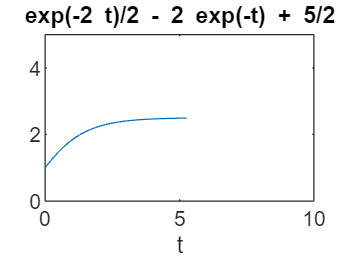

ezplot(ySol)
xlim([0 10]);
ylim([0 5]);